# Initial Value Problems

Name & Date

Solve and plot solutions to firsdt order initial value problems of the form 


$$\frac{dx}{dt} = f(x,t) \\
x_0(t_0) = x_0$$
 

where $x(t)$ is the unknown function of the independent variable $t$ and $x_0$ is the initial value of $x$ at the initial value at time $t_0$.

First, obtain the direction field for the diff. eq. determined by the RHS.

Consider the problem for $f(t,x) = t+x$, then obtain the direction field using the matlab function 'quiver.'

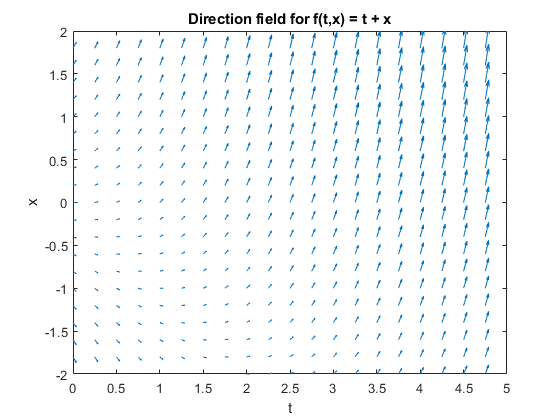

trange = linspace(0,5,21);
xrange = linspace(-2,2,21);
[T,X] = meshgrid(trange,xrange);
dx = T + X;
dt = ones(size(dx));
quiver(T,X,dt,dx);
ylabel('x');xlabel('t'); axis([0 5 -2 2]);
title('Direction field for f(t,x) = t + x');

Now, consider $\frac{dx}{dt} = t+x$ with $x(0) = 0$ bring the initial condition. Then, the solution of the initial value problem is the unique curve that passes through that point and remains tangent to the arrows in the direction field.

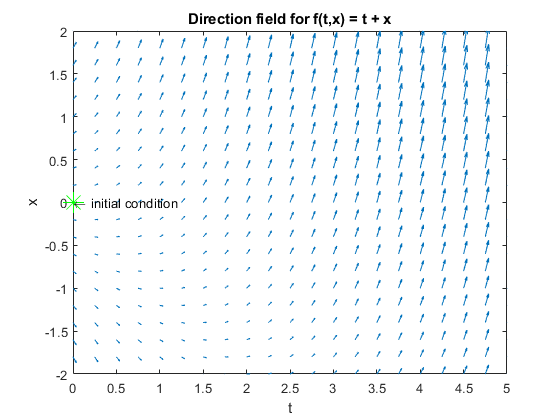

trange = linspace(0,5,21);
xrange = linspace(-2,2,21);
[T,X] = meshgrid(trange,xrange);
dx = T + X;
dt = ones(size(dx));
quiver(T,X,dt,dx);
ylabel('x');xlabel('t'); axis([0 5 -2 2]);
title('Direction field for f(t,x) = t + x');
hold on;
plot(0,0,'*g','MarkerSize',15);
text(0,0,'\leftarrow initial condition','HorizontalAlignment','left');
hold off;

Now we will use the function ode45 to obtain a numerical solution to the IVP


$$\frac{dx}{dt} = t+x\\
x(0) = 0$$


ode45(f, tspan, x_0);

Where f is the function corrosponding to the RHS of the diff. eq.

    tspan is a vector with the time interval

    x0 is the initial value of the unknown

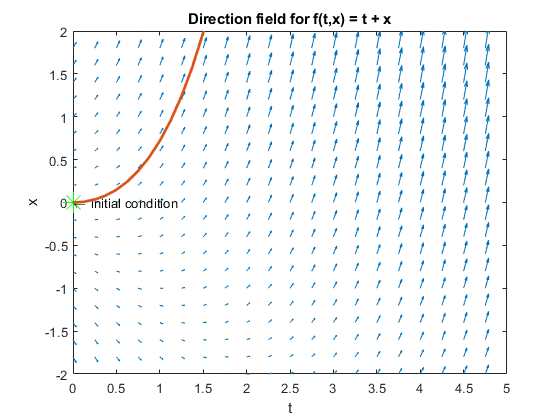

quiver(T,X,dt,dx);
ylabel('x');xlabel('t'); axis([0 5 -2 2]);
title('Direction field for f(t,x) = t + x');
hold on;
plot(0,0,'*g','MarkerSize',15);
text(0,0,'\leftarrow initial condition','HorizontalAlignment','left');

f = @(t,x) t+x;
tspan = [0 5];
x0=0;
[t,x] = ode45(f,tspan,x0);

plot(t,x,'LineWidth',2);
hold off;